## **Tuberculosis testing**

Combines drug interactions from following:

- Suraj's dataset - supplementary_tables_ver4.xlsx

- Original INDIGO paper - Appendix Table S5

%make sure you are starting in folder one step above code, data and results
%folders
testFile = 'tb_data.xlsx';
valMethod = 'cv';
K = 5;
orthology = 'ecoli_mtb_orthologs.xlsx';
trainingData = 'indigo';

summaryTable = 1×11 table
      min      median     max      range       mean       std      interactionCount    synergyCount    antagonismCount    rejectNormality    pNormality
    _______    ______    ______    ______    ________    ______    ________________    ____________    _______________    _______________    __________

    -2.1844      0       2.0875    4.2719    -0.25897    0.7209           67                27               13                true            0.0005  


drugList = 24×1 cell array
    {0×0 char         }
    {'AMIKACIN'       }
    {'AMP'            }
    {'AZITHROMYCIN'   }
    {'CEFACLOR'       }
    {'CHLORAMPHENICOL'}
    {'CIPROFLOXACIN'  }
    {'CLARYTHROMYCIN' }
    {'CYCLOSERINED'   }
    {'ERYTHROMYCIN'   }
    {'FUSIDICACID'    }
    {'INH'            }
    {'LEVO'           }
    {'MINOCYCLINE'    }
    {'MMC'            }
    {'NIGERICIN'      }
    {'NOVOBIOCIN'     }
    {'OXACILLIN'      }
    {'RIF'            }
    {'SM'             }
    {'SPECTINOMYCIN'  }
    {'SPT'            }
    {'TET'            }
    {'VANCOMYCIN'     }


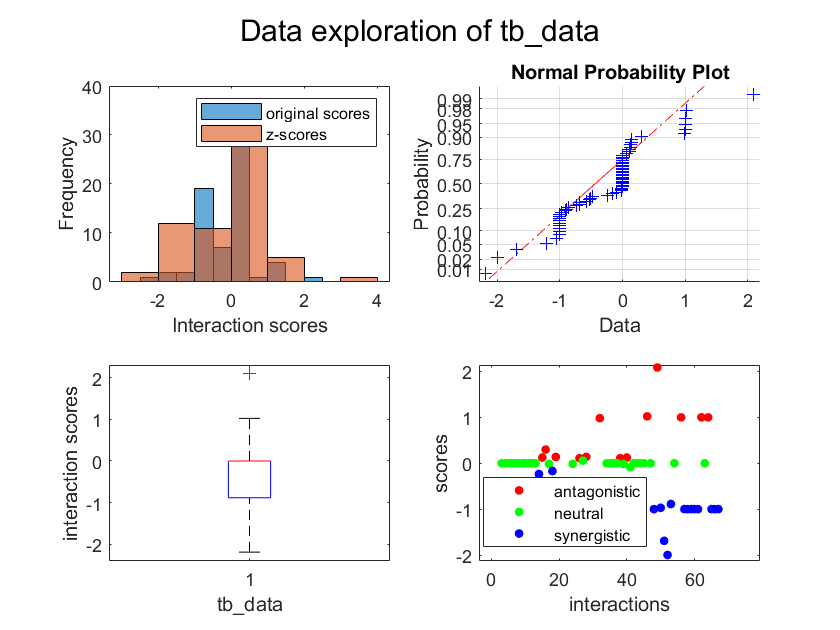

[summary,drugList] = dataExplore(testFile);

indigoSummary = indigoRun(testFile,valMethod,K,orthology,trainingData);

Run 1
Elapsed time is 15.096970 seconds.
Run 2
Elapsed time is 14.764904 seconds.
Run 3
Elapsed time is 14.935269 seconds.
Run 4
Elapsed time is 15.366362 seconds.
Run 5
Elapsed time is 16.053828 seconds.


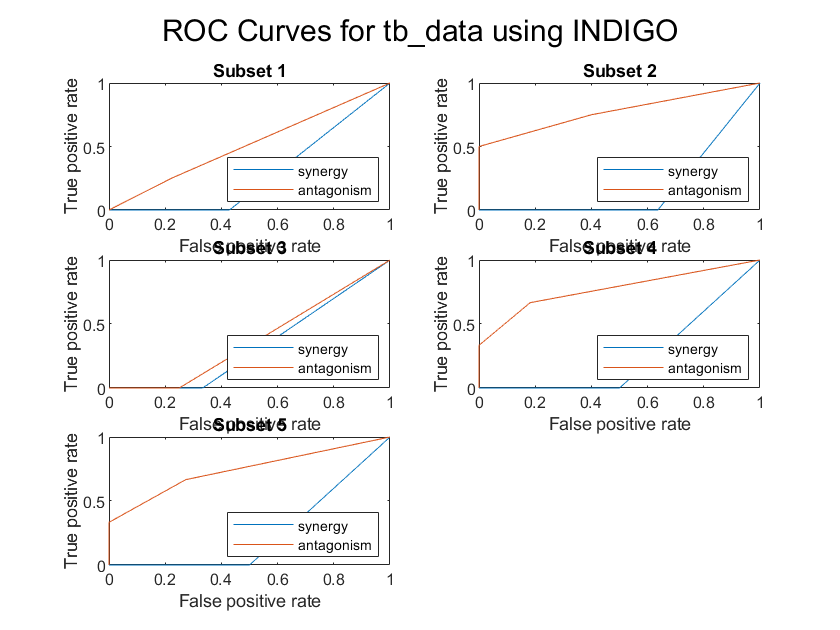

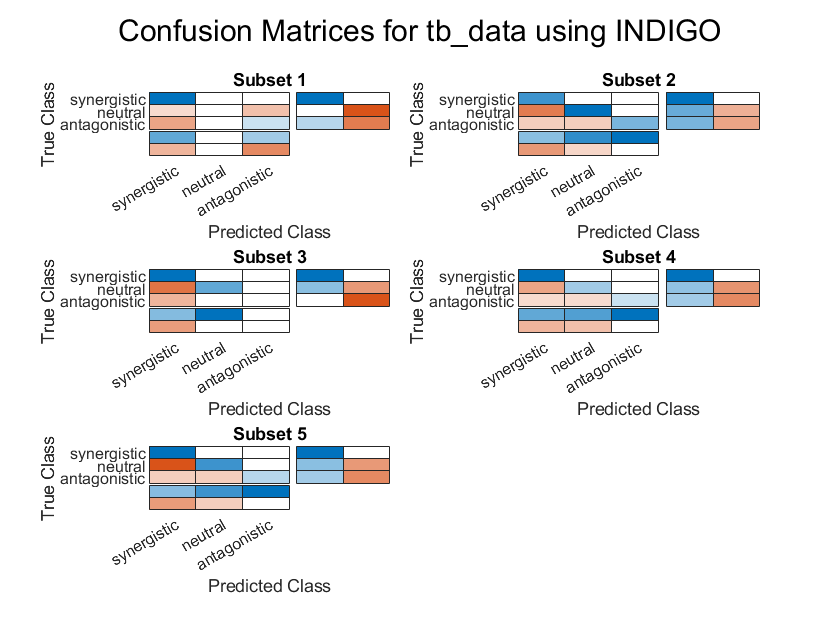

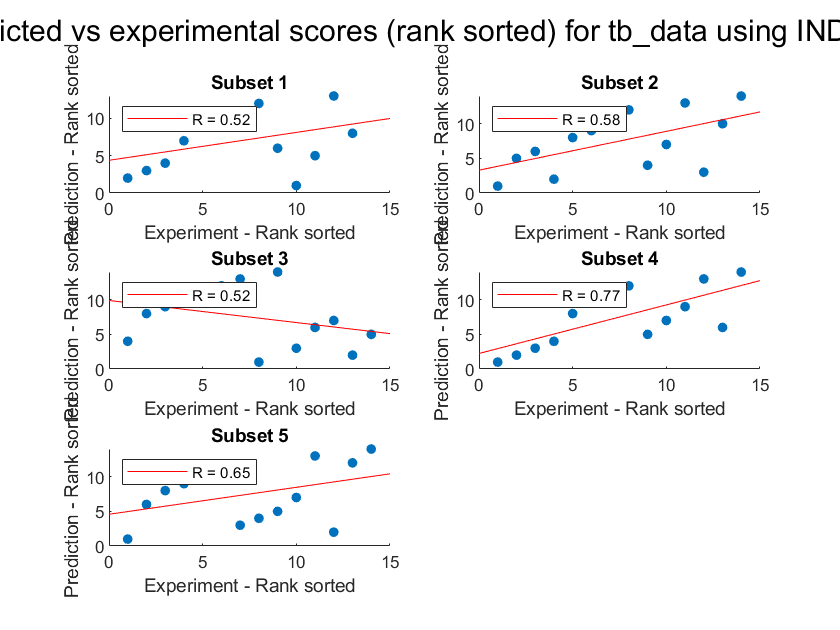

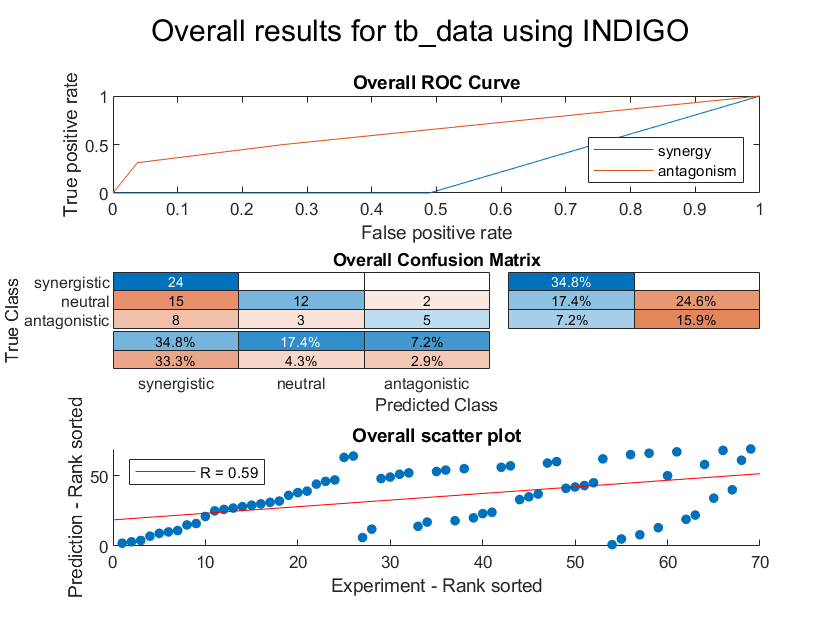

resultsTable = 5×12 table
                Interactions    R (rank)     P value     Accuracy    Absolute error    Precision (synergy)    Recall (synergy)    Precision (antagonism)    Recall (antagonism)    Guess Accuracy (p value)    AUC - ROC (synergy)    AUC - ROC (antagonism)
                ____________    ________    _________    ________    ______________    ___________________    ________________    ______________________    ___________________    ________________________    ___________________    ______________________

    Subset 1         13         0.52494   

averagesTable = 12×1 table
                                  Value   
                                __________

    Interactions                      13.8
    R (rank)                       0.60756
    P value                       0.033043
    Accuracy                       0.59341
    Absolute error                 0.52418
    Precision (synergy)            0.50551
    Recall (synergy)                     1
    Precision (antagonism)             NaN
    Recall (antagonism)            0.28333
    Guess Accuracy (p value)    5.4431e-05
    AUC - ROC (synergy)            0.26017
    AUC - ROC (antagonism)         0.63581


overviewTable = 12×1 table
                                  Value   
                                __________

    Interactions                        69
    R (rank)                       0.58539
    P value                     1.2709e-07
    Accuracy                        0.5942
    Absolute error                 0.52174
    Precision (synergy)            0.51064
    Recall (synergy)                     1
    Precision (antagonism)         0.71429
    Recall (antagonism)             0.3125
    Guess Accuracy (p value)    1.4072e-14
    AUC - ROC (synergy)            0.25556
    AUC - ROC (antagonism)         0.64976


[stats,averages,overview] = analyze(indigoSummary);

save(saveIndigo(indigoSummary))

%z scores
testFile = 'tb_data.xlsx';
valMethod = 'cv';
K = 5;
orthology = 'ecoli_mtb_orthologs.xlsx';
trainingData = 'indigo';
standardize = 'standardized';

indigoSummary = indigoRun(testFile,valMethod,K,orthology,trainingData,'',standardize);

Run 1
Elapsed time is 16.071107 seconds.
Run 2
Elapsed time is 15.898629 seconds.
Run 3
Elapsed time is 16.045603 seconds.
Run 4
Elapsed time is 17.895947 seconds.
Run 5
Elapsed time is 28.232767 seconds.


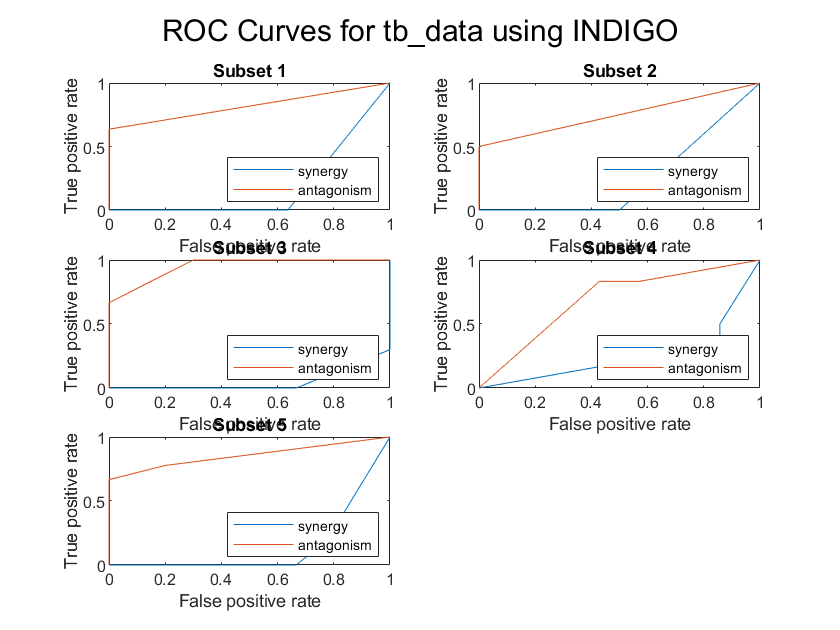

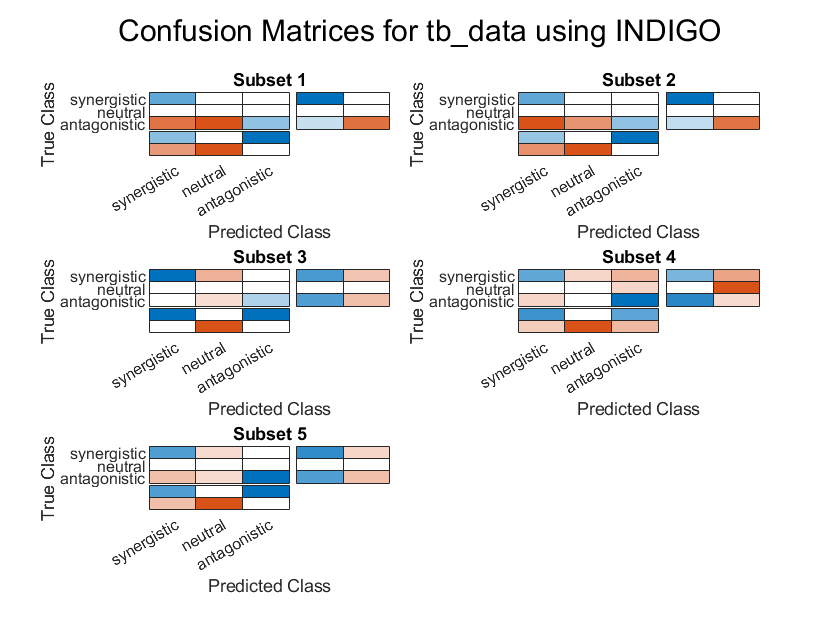

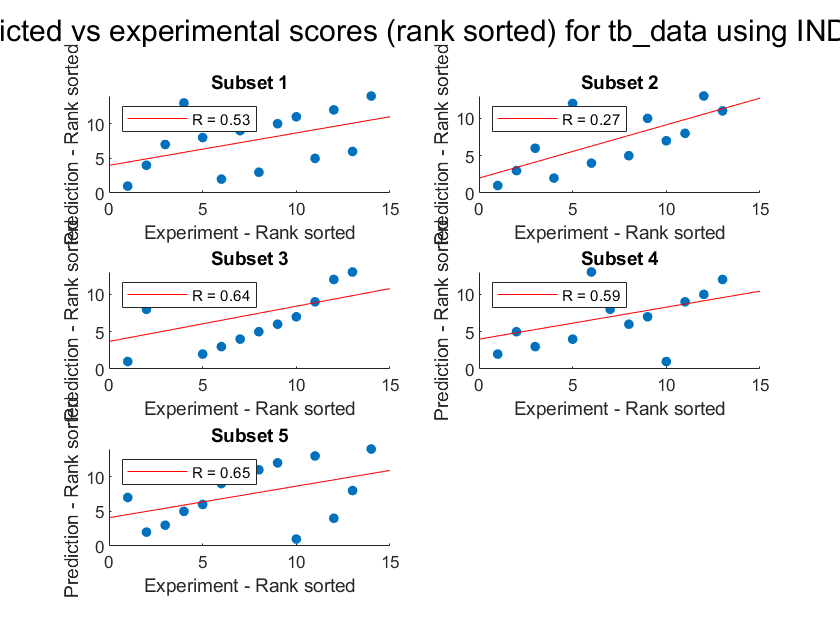

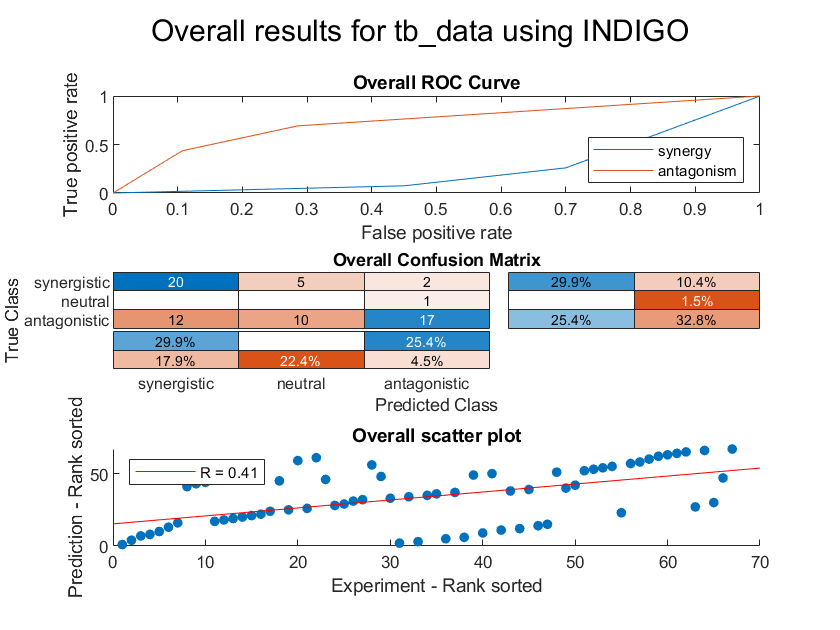

resultsTable = 5×12 table
                Interactions    R (rank)    P value     Accuracy    Absolute error    Precision (synergy)    Recall (synergy)    Precision (antagonism)    Recall (antagonism)    Guess Accuracy (p value)    AUC - ROC (synergy)    AUC - ROC (antagonism)
                ____________    ________    ________    ________    ______________    ___________________    ________________    ______________________    ___________________    ________________________    ___________________    ______________________

    Subset 1         14         0.52855     

averagesTable = 12×1 table
                                 Value  
                                ________

    Interactions                    13.4
    R (rank)                      0.5338
    P value                     0.097867
    Accuracy                     0.55275
    Absolute error               0.65604
    Precision (synergy)          0.64405
    Recall (synergy)                 0.8
    Precision (antagonism)         0.925
    Recall (antagonism)           0.5097
    Guess Accuracy (p value)           0
    AUC - ROC (synergy)          0.17525
    AUC - ROC (antagonism)       0.81284


overviewTable = 12×1 table
                                  Value   
                                __________

    Interactions                        67
    R (rank)                       0.41312
    P value                     0.00051186
    Accuracy                       0.55224
    Absolute error                 0.65672
    Precision (synergy)              0.625
    Recall (synergy)               0.74074
    Precision (antagonism)            0.85
    Recall (antagonism)             0.4359
    Guess Accuracy (p value)             0
    AUC - ROC (synergy)            0.24722
    AUC - ROC (antagonism)         0.72848


[stats,averages,overview] = analyze(indigoSummary);

save(saveIndigo(indigoSummary))

testFile = 'tb_data.xlsx';
valMethod = 'cv';
K = 5;
orthology = 'ecoli_mtb_orthologs.xlsx';
trainingData = 'nature';
standardize = '';

indigoSummary = indigoRun(testFile,valMethod,K,orthology,trainingData);

Run 1
Elapsed time is 144.836948 seconds.
Run 2
Elapsed time is 117.802044 seconds.
Run 3
Elapsed time is 99.547788 seconds.
Run 4
Elapsed time is 143.449426 seconds.
Run 5
Elapsed time is 144.655834 seconds.


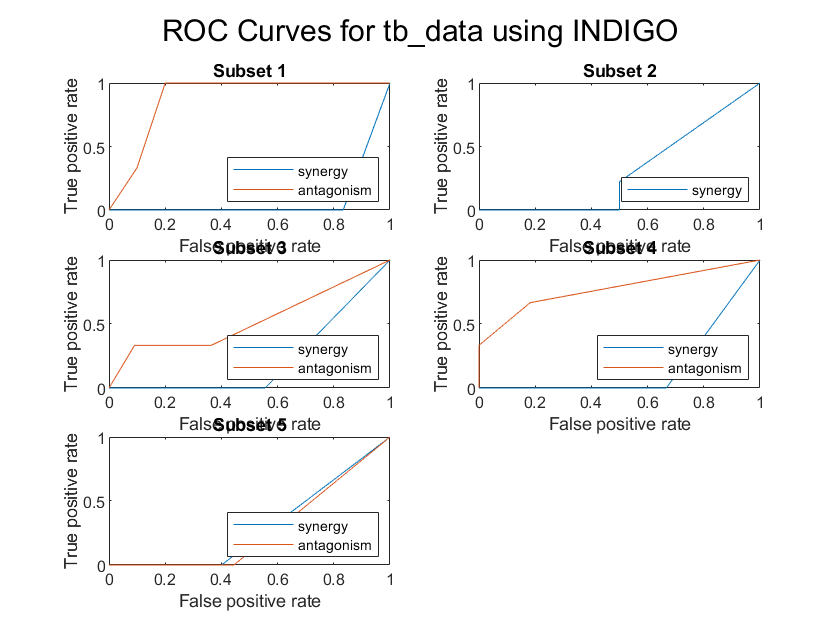

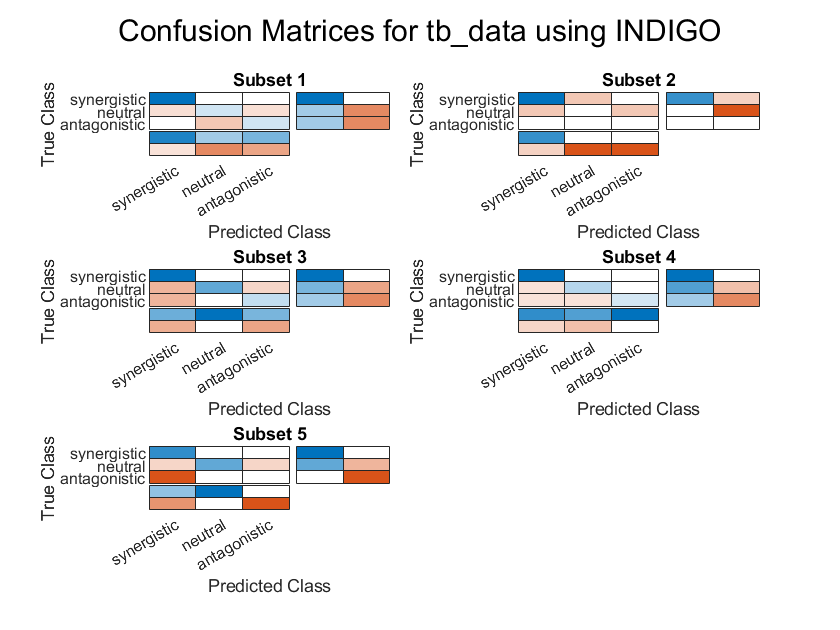

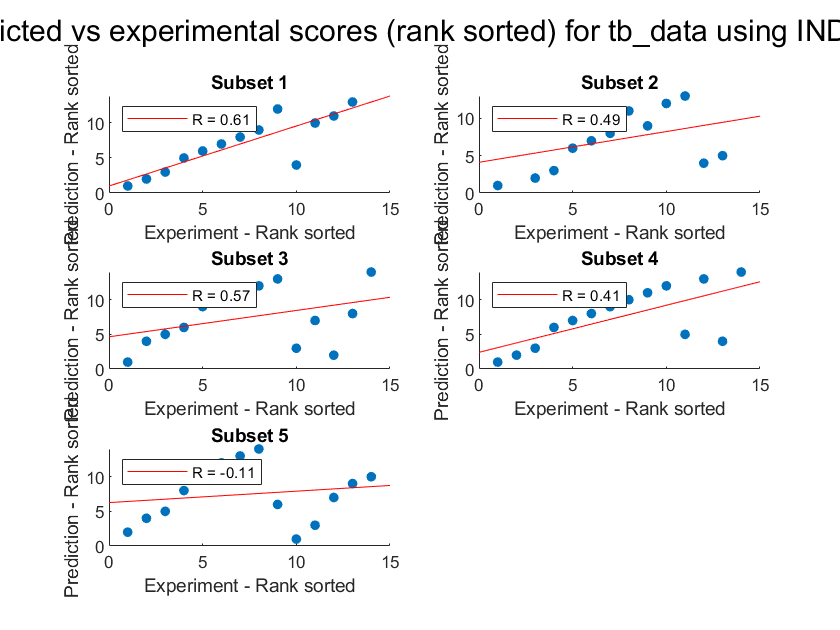

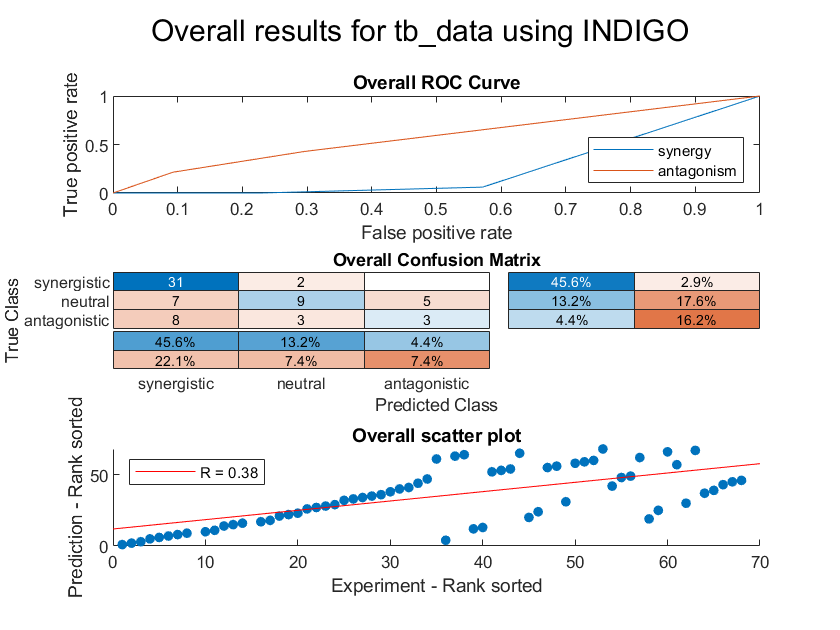

resultsTable = 5×12 table
                Interactions    R (rank)    P value     Accuracy    Absolute error    Precision (synergy)    Recall (synergy)    Precision (antagonism)    Recall (antagonism)    Guess Accuracy (p value)    AUC - ROC (synergy)    AUC - ROC (antagonism)
                ____________    ________    ________    ________    ______________    ___________________    ________________    ______________________    ___________________    ________________________    ___________________    ______________________

    Subset 1         13          0.61459    

averagesTable = 12×1 table
                                  Value   
                                __________

    Interactions                      13.6
    R (rank)                       0.39422
    P value                        0.20159
    Accuracy                       0.63187
    Absolute error                 0.48242
    Precision (synergy)            0.68167
    Recall (synergy)               0.95556
    Precision (antagonism)             0.4
    Recall (antagonism)                NaN
    Guess Accuracy (p value)    0.00021322
    AUC - ROC (synergy)            0.21556
    AUC - ROC (antagonism)             NaN


overviewTable = 12×1 table
                                  Value   
                                __________

    Interactions                        68
    R (rank)                       0.38378
    P value                      0.0012348
    Accuracy                       0.63235
    Absolute error                 0.48529
    Precision (synergy)            0.67391
    Recall (synergy)               0.93939
    Precision (antagonism)           0.375
    Recall (antagonism)            0.21429
    Guess Accuracy (p value)    5.1426e-16
    AUC - ROC (synergy)            0.23766
    AUC - ROC (antagonism)         0.57804


[stats,averages,overview] = analyze(indigoSummary);

save(saveIndigo(indigoSummary))

%z scores
testFile = 'tb_data.xlsx';
valMethod = 'cv';
K = 5;
orthology = 'ecoli_mtb_orthologs.xlsx';
trainingData = 'nature';
standardize = 'standardized';

Run 1
Elapsed time is 108.613663 seconds.
Run 2
Elapsed time is 150.872083 seconds.
Run 3
Elapsed time is 98.798647 seconds.
Run 4
Elapsed time is 82.850105 seconds.
Run 5
Elapsed time is 96.943441 seconds.


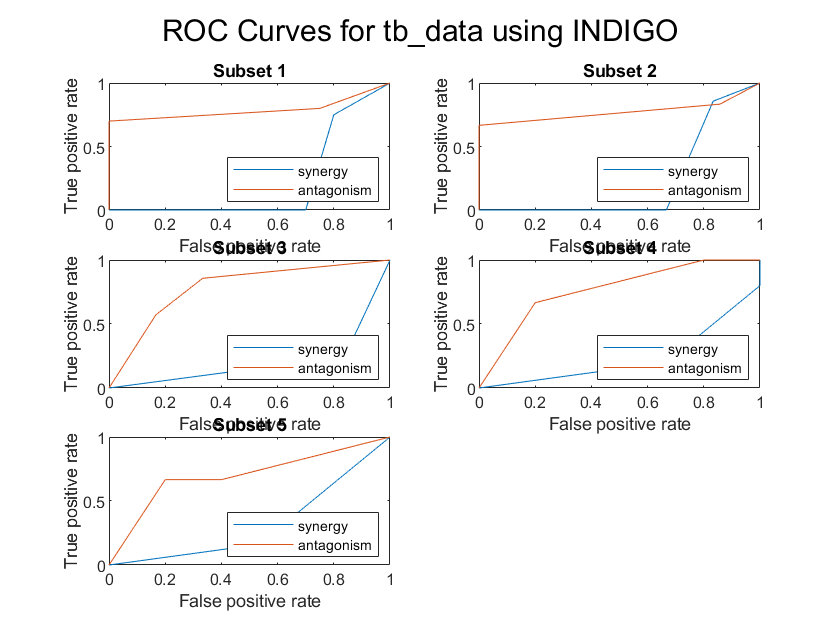

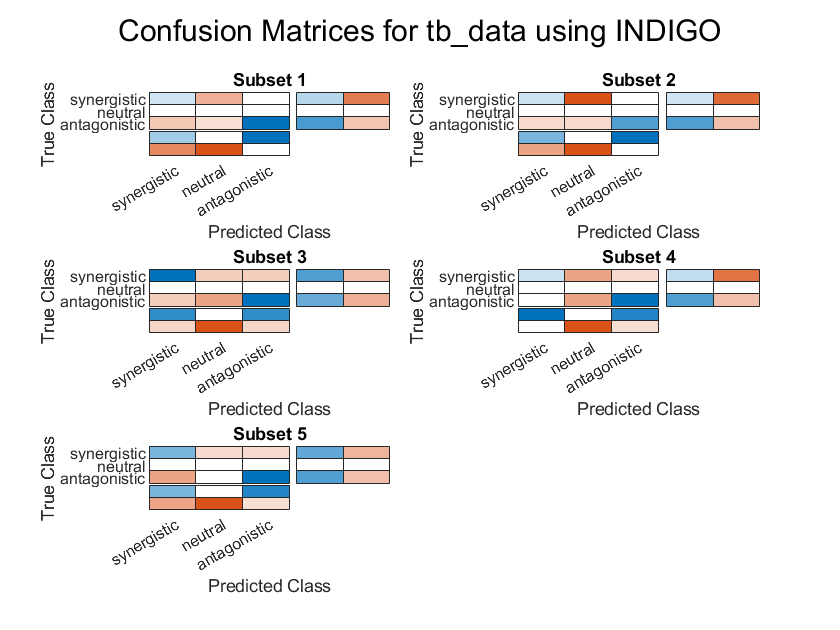

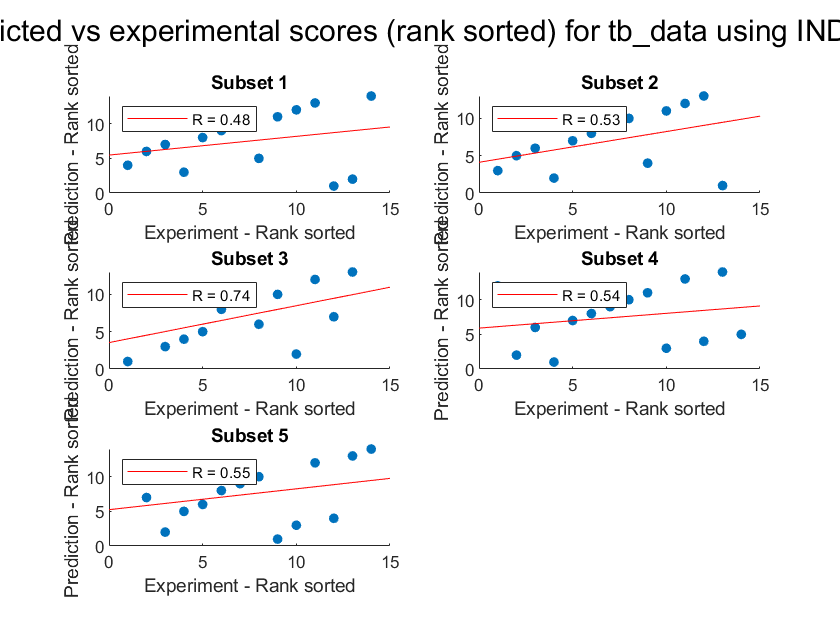

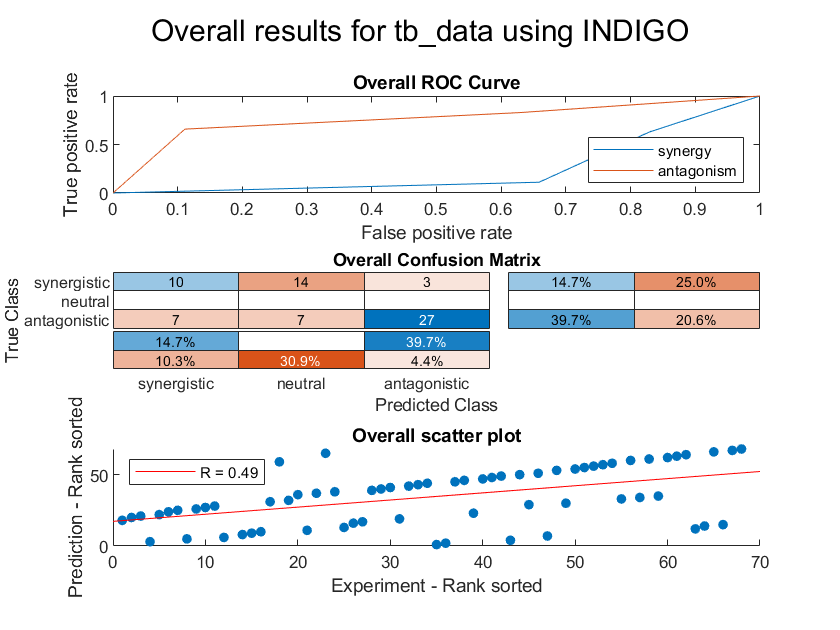

resultsTable = 5×12 table
                Interactions    R (rank)     P value     Accuracy    Absolute error    Precision (synergy)    Recall (synergy)    Precision (antagonism)    Recall (antagonism)    Guess Accuracy (p value)    AUC - ROC (synergy)    AUC - ROC (antagonism)
                ____________    ________    _________    ________    ______________    ___________________    ________________    ______________________    ___________________    ________________________    ___________________    ______________________

    Subset 1         14         0.48371   

averagesTable = 12×1 table
                                 Value  
                                ________

    Interactions                    13.6
    R (rank)                     0.56969
    P value                     0.045934
    Accuracy                     0.54286
    Absolute error                0.6033
    Precision (synergy)          0.62667
    Recall (synergy)              0.3719
    Precision (antagonism)       0.90286
    Recall (antagonism)          0.65429
    Guess Accuracy (p value)           0
    AUC - ROC (synergy)          0.23726
    AUC - ROC (antagonism)       0.76274


overviewTable = 12×1 table
                                  Value   
                                __________

    Interactions                        68
    R (rank)                       0.49465
    P value                     1.8054e-05
    Accuracy                       0.54412
    Absolute error                 0.60294
    Precision (synergy)            0.58824
    Recall (synergy)               0.37037
    Precision (antagonism)             0.9
    Recall (antagonism)            0.65854
    Guess Accuracy (p value)             0
    AUC - ROC (synergy)            0.23893
    AUC - ROC (antagonism)         0.76107


indigoSummary = indigoRun(testFile,valMethod,K,orthology,trainingData,'',standardize);

save(saveIndigo(indigoSummary))

testFile = 'tb_data.xlsx';
valMethod = 'cv';
K = 5;
orthology = 'ecoli_mtb_orthologs.xlsx';
trainingData = 'nature_ecoli';
standardize = '';

indigoSummary = indigoRun(testFile,valMethod,K,orthology,trainingData);

Run 1
Elapsed time is 10.954096 seconds.
Run 2
Elapsed time is 10.838402 seconds.
Run 3
Elapsed time is 11.025999 seconds.
Run 4
Elapsed time is 10.720933 seconds.
Run 5
Elapsed time is 12.292326 seconds.


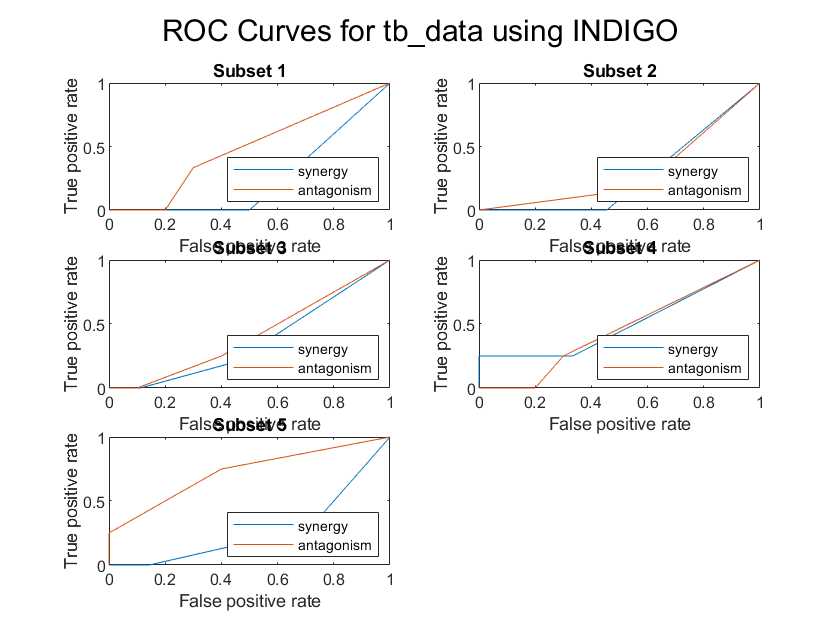

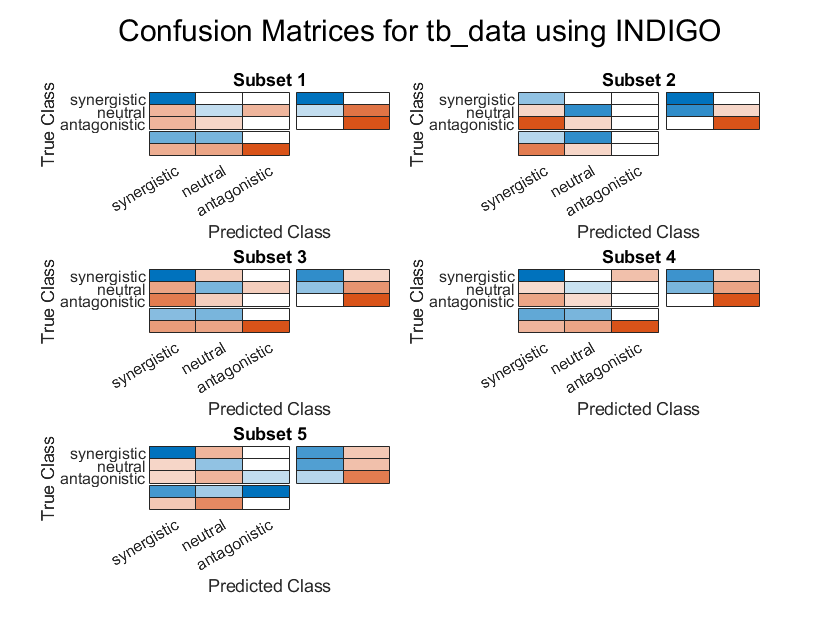

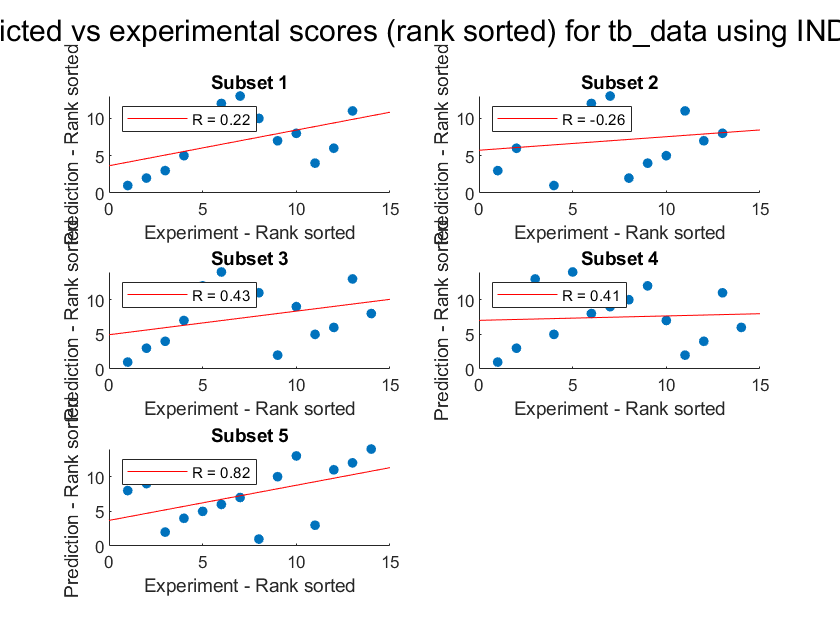

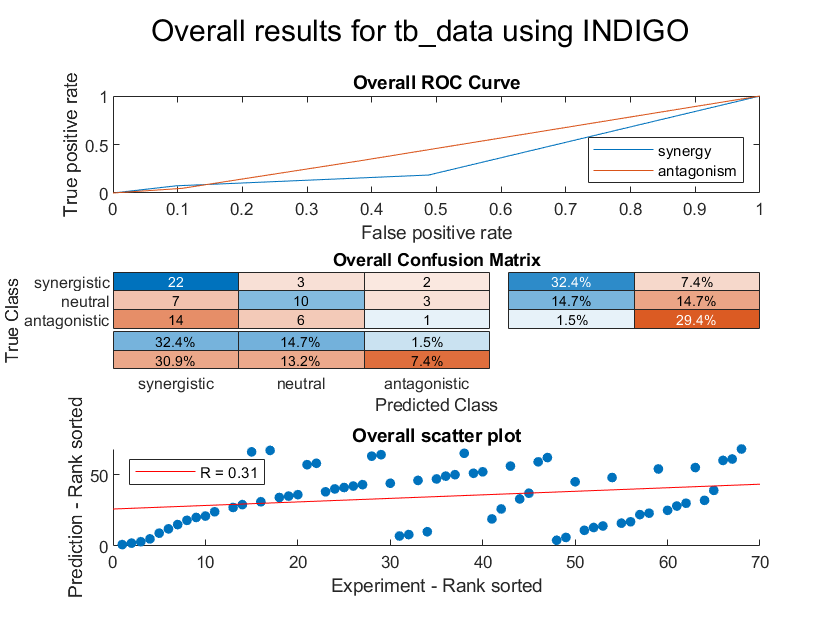

resultsTable = 5×12 table
                Interactions    R (rank)     P value      Accuracy    Absolute error    Precision (synergy)    Recall (synergy)    Precision (antagonism)    Recall (antagonism)    Guess Accuracy (p value)    AUC - ROC (synergy)    AUC - ROC (antagonism)
                ____________    ________    __________    ________    ______________    ___________________    ________________    ______________________    ___________________    ________________________    ___________________    ______________________

    Subset 1         13           0.2179

averagesTable = 12×1 table
                                 Value 
                                _______

    Interactions                   13.6
    R (rank)                    0.32438
    P value                     0.22822
    Accuracy                    0.48462
    Absolute error              0.75165
    Precision (synergy)         0.51286
    Recall (synergy)            0.85286
    Precision (antagonism)          NaN
    Recall (antagonism)            0.05
    Guess Accuracy (p value)    0.00967
    AUC - ROC (synergy)         0.33094
    AUC - ROC (antagonism)      0.47369


overviewTable = 12×1 table
                                  Value   
                                __________

    Interactions                        68
    R (rank)                       0.31297
    P value                      0.0093598
    Accuracy                       0.48529
    Absolute error                    0.75
    Precision (synergy)            0.51163
    Recall (synergy)               0.81481
    Precision (antagonism)         0.16667
    Recall (antagonism)           0.047619
    Guess Accuracy (p value)    5.7301e-22
    AUC - ROC (synergy)            0.35772
    AUC - ROC (antagonism)         0.46657


[stats,averages,overview] = analyze(indigoSummary);

save(saveIndigo(indigoSummary))

testFile = 'tb_data.xlsx';
valMethod = 'cv';
K = 5;
orthology = 'ecoli_mtb_orthologs.xlsx';
trainingData = 'nature_ecoli';
standardize = 'standardized';

indigoSummary = indigoRun(testFile,valMethod,K,orthology,trainingData,'',standardize);

Run 1
Elapsed time is 10.206431 seconds.
Run 2
Elapsed time is 10.198427 seconds.
Run 3
Elapsed time is 10.749708 seconds.
Run 4
Elapsed time is 10.232514 seconds.
Run 5
Elapsed time is 9.979279 seconds.


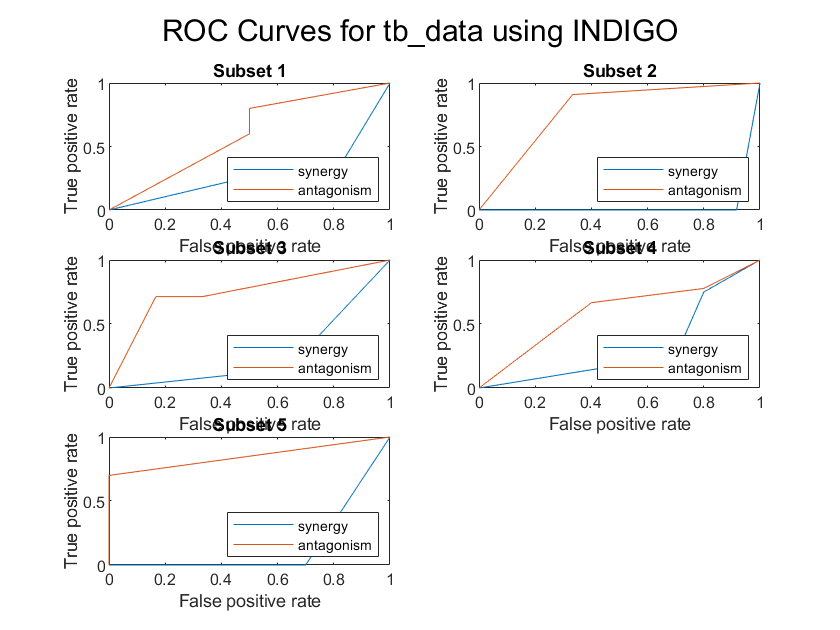

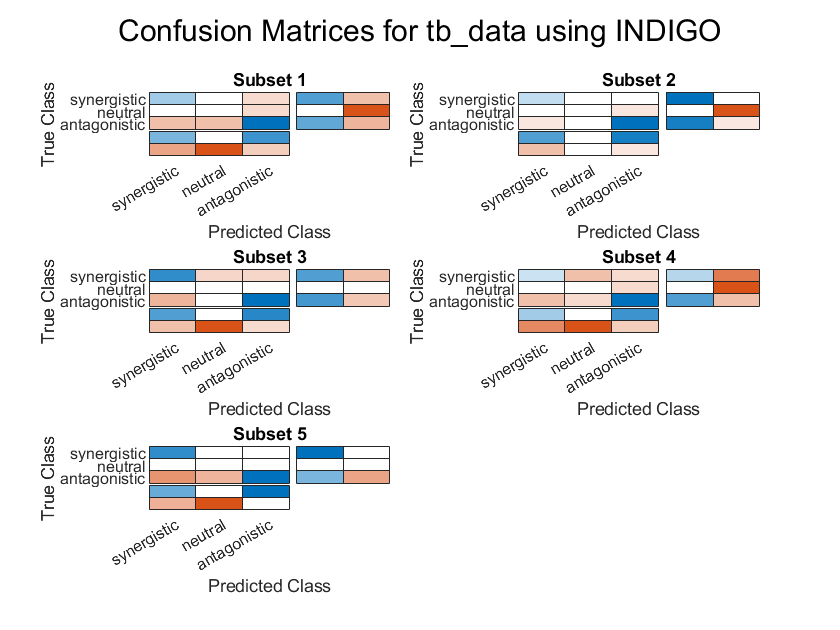

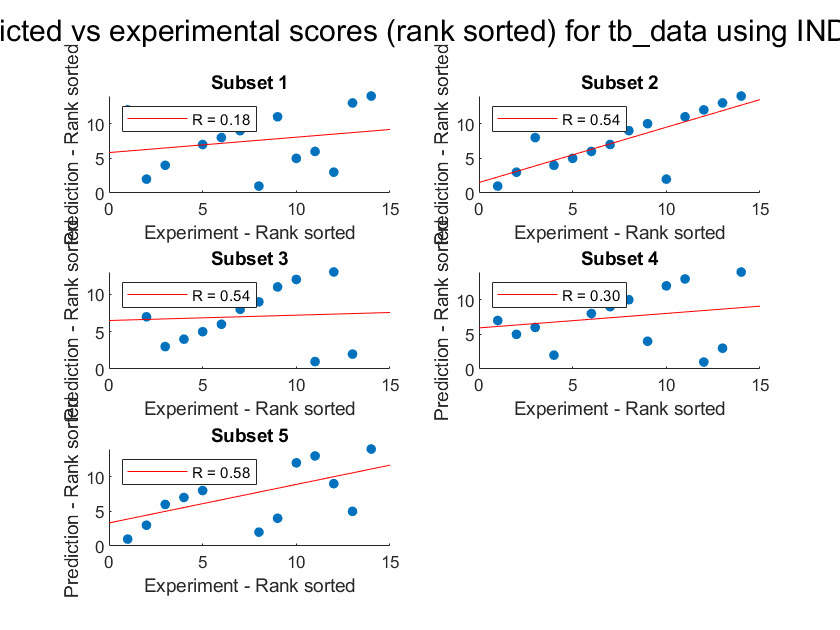

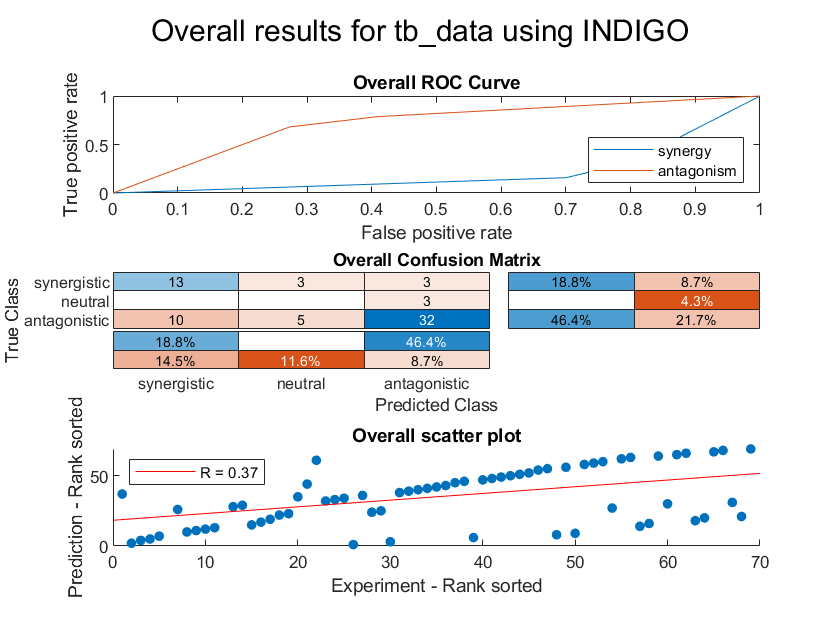

resultsTable = 5×12 table
                Interactions    R (rank)    P value     Accuracy    Absolute error    Precision (synergy)    Recall (synergy)    Precision (antagonism)    Recall (antagonism)    Guess Accuracy (p value)    AUC - ROC (synergy)    AUC - ROC (antagonism)
                ____________    ________    ________    ________    ______________    ___________________    ________________    ______________________    ___________________    ________________________    ___________________    ______________________

    Subset 1         14         0.18092     

averagesTable = 12×1 table
                                 Value 
                                _______

    Interactions                   13.8
    R (rank)                    0.42666
    P value                     0.19342
    Accuracy                    0.65275
    Absolute error              0.53626
    Precision (synergy)         0.54762
    Recall (synergy)            0.71667
    Precision (antagonism)      0.84848
    Recall (antagonism)         0.67801
    Guess Accuracy (p value)          0
    AUC - ROC (synergy)         0.20841
    AUC - ROC (antagonism)      0.71758


overviewTable = 12×1 table
                                  Value  
                                _________

    Interactions                       69
    R (rank)                      0.37021
    P value                     0.0017419
    Accuracy                      0.65217
    Absolute error                0.53623
    Precision (synergy)           0.56522
    Recall (synergy)              0.68421
    Precision (antagonism)        0.84211
    Recall (antagonism)           0.68085
    Guess Accuracy (p value)            0
    AUC - ROC (synergy)           0.21053
    AUC - ROC (antagonism)        0.72099


[stats,averages,overview] = analyze(indigoSummary);

save(saveIndigo(indigoSummary))